# Example: Iterative fitting for multiple provinces in China  (22-Jan-2020 - )

In this example, the generalized SEIR model is automatically fitted to multiple provinces in China. As in the prvious examples, I am taking some data, collected into DATA.mat from John Hopkins university [1]. To keep the computation as short as possible, the option "iter" is removed using an optional argument.

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
clearvars;close all;clc;
% Download the data from ref [1] and read them with the function getDataCOVID
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID();
fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 22-Mar-2020



try
    indLocation = find(contains(tableRecovered.CountryRegion,'China')==1);
catch exception
    searchLoc = strfind(tableRecovered.CountryRegion,'China')
    indLocation = find([searchLoc{:}]==1)
end

tableRecovered(indLocation,1:2)

ans = 33×2 table
    ProvinceState     CountryRegion
    ______________    _____________

    "Hubei"              "China"   
    "Guangdong"          "China"   
    "Henan"              "China"   
    "Zhejiang"           "China"   
    "Hunan"              "China"   
    "Anhui"              "China"   
    "Jiangxi"            "China"   
    "Shandong"           "China"   
    "Jiangsu"            "China"   
    "Chongqing"          "China"   
    "Sichuan"            "China"   
    "Heilongjiang"       "China"   
    "Beijing"            "China"   
    "Shanghai"           "China"   
    "Hebei"              "China"   
    "Fujian"             "China"   


minNum= 40; % The initial conditions requires here at least 40 confirmed infectious. Otherwise the fit may not be reliable

## Iterative application of fit_SEIQRDP

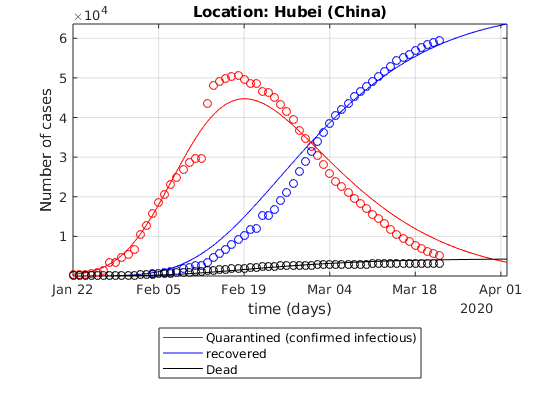

Elapsed time is 3.644414 seconds.


Elapsed time is 3.316443 seconds.


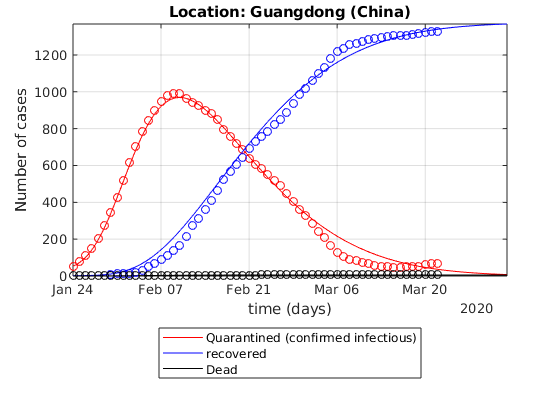

Elapsed time is 2.279408 seconds.


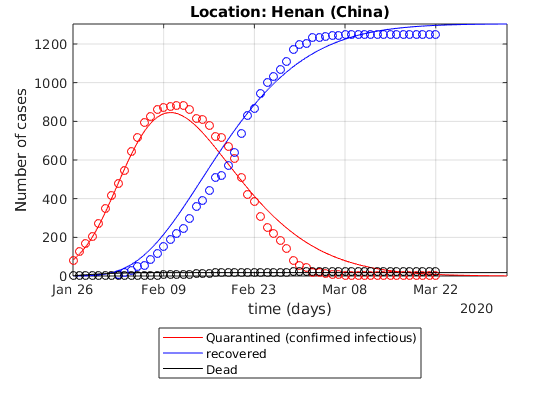

Elapsed time is 3.411178 seconds.


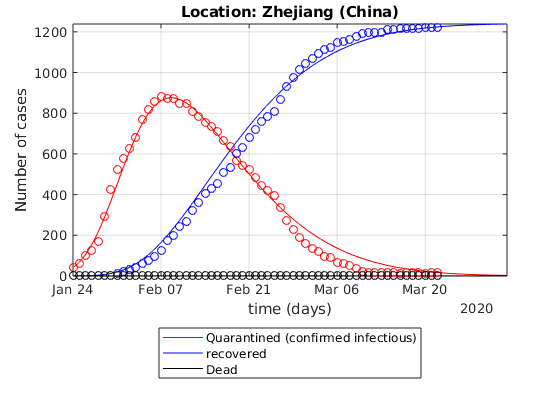

Elapsed time is 3.223497 seconds.


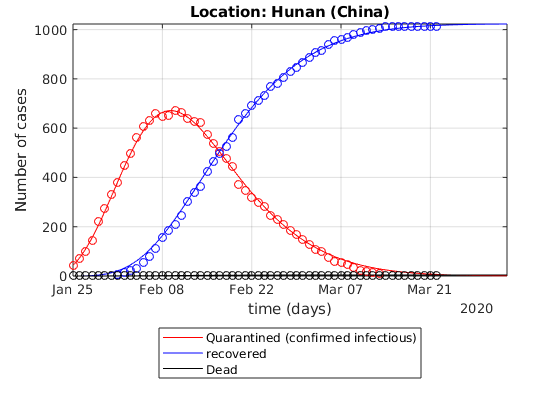

Elapsed time is 2.254360 seconds.


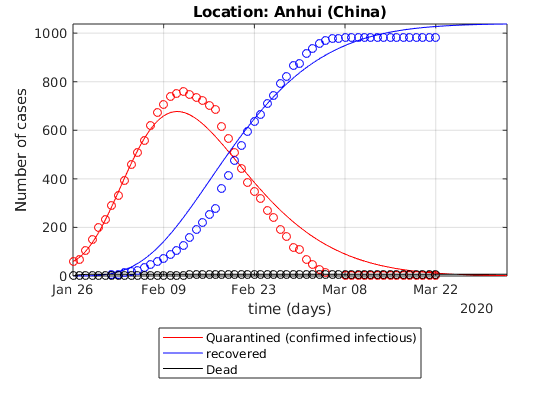

Elapsed time is 3.066635 seconds.


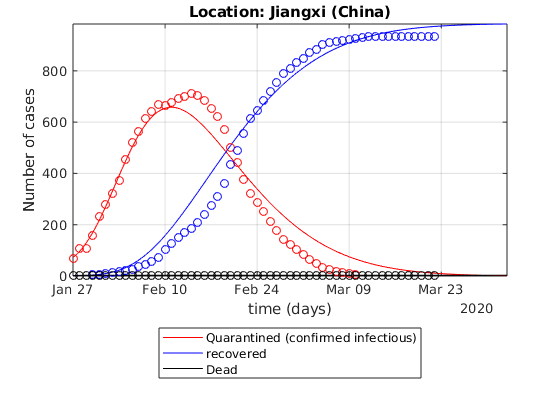

Elapsed time is 3.134197 seconds.


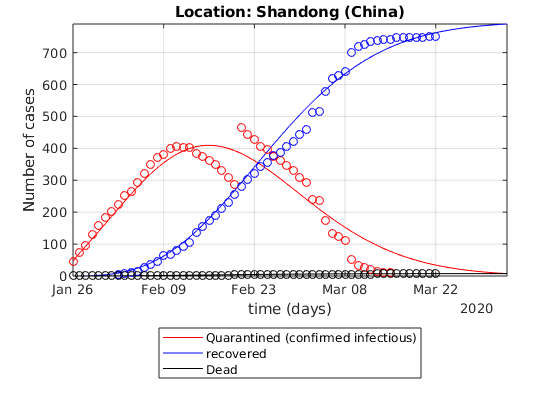

Elapsed time is 2.873756 seconds.


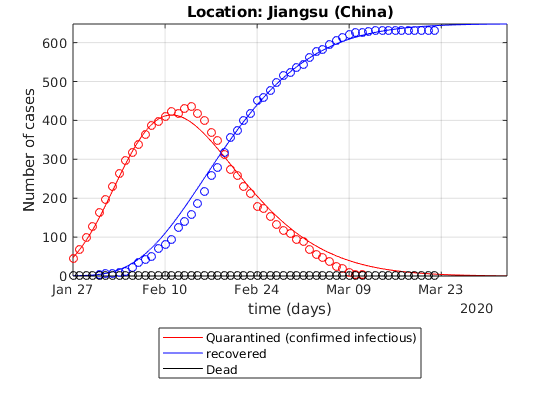

Elapsed time is 3.120705 seconds.


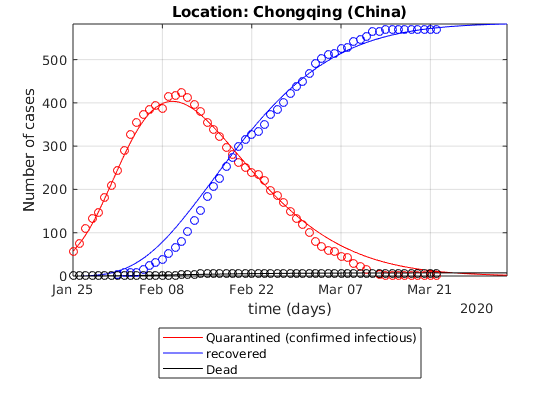

Elapsed time is 3.390790 seconds.


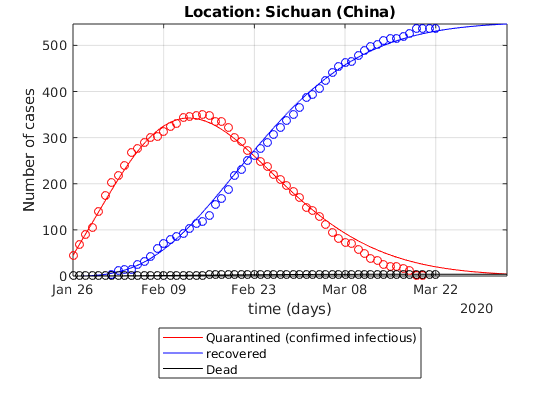

Elapsed time is 2.884088 seconds.


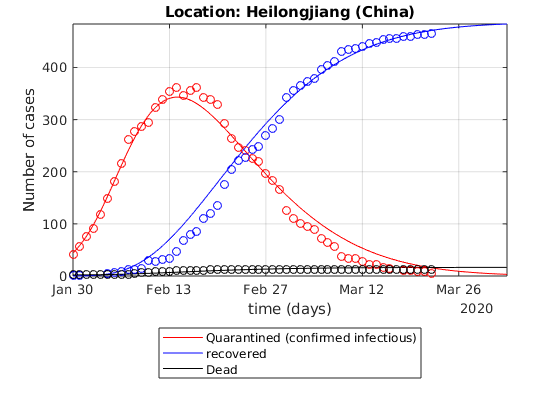

Elapsed time is 1.574532 seconds.


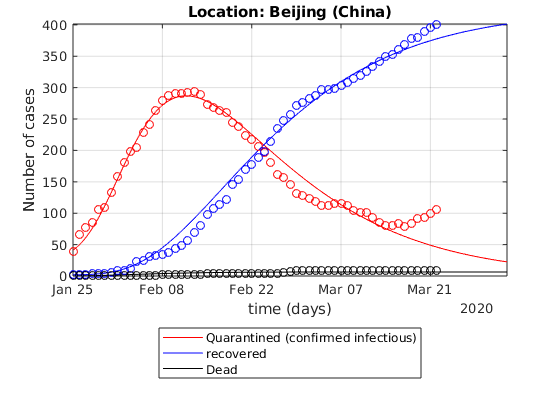

Elapsed time is 2.814026 seconds.


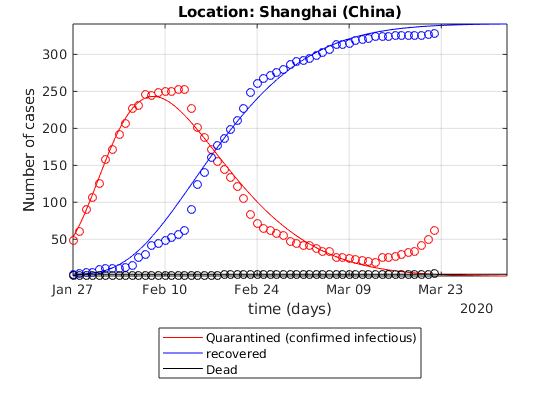

Elapsed time is 2.162540 seconds.


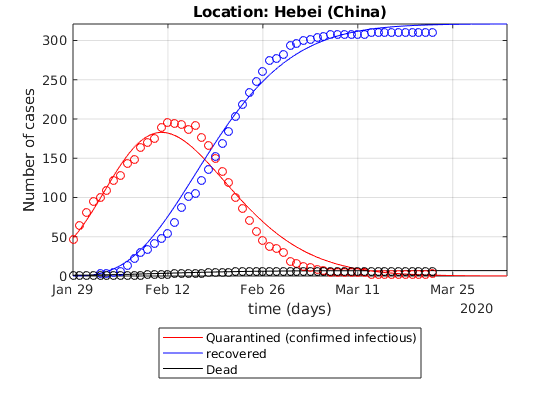

Elapsed time is 3.246538 seconds.


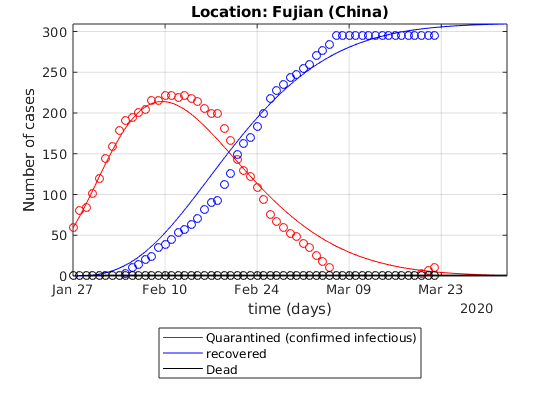

Elapsed time is 2.668893 seconds.


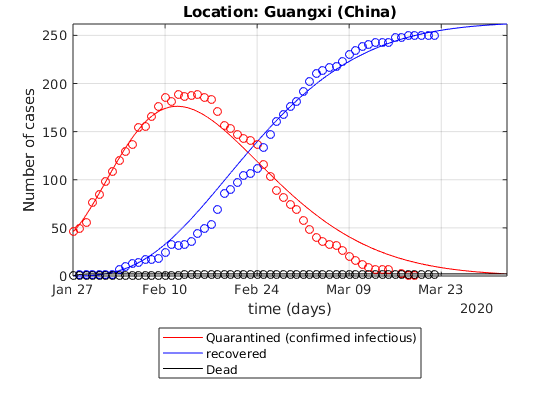

Elapsed time is 3.181846 seconds.


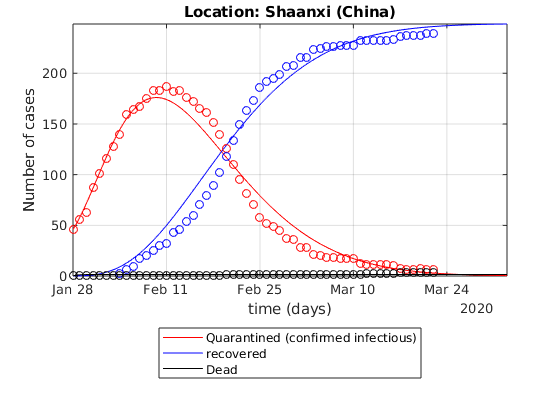

Elapsed time is 2.596458 seconds.


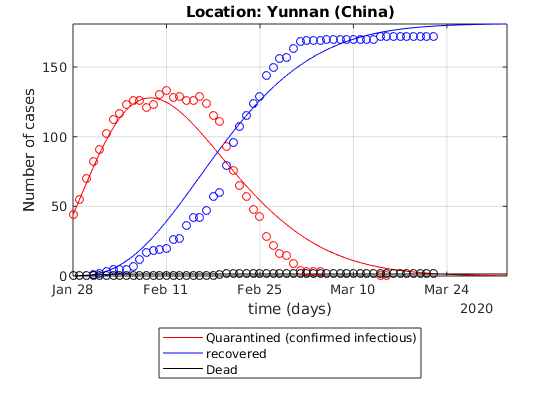

Elapsed time is 2.904904 seconds.


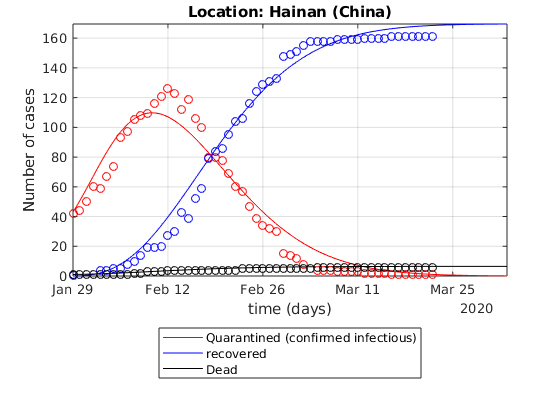

Elapsed time is 1.730721 seconds.


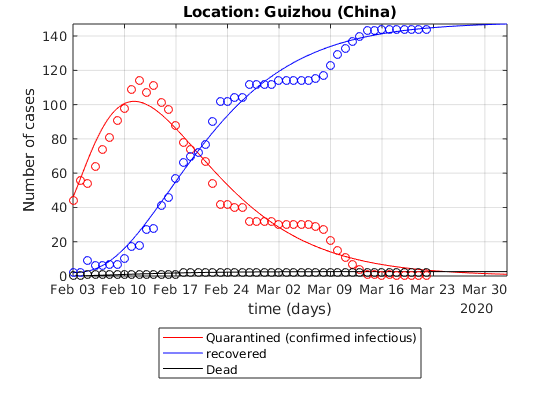

Elapsed time is 1.785169 seconds.


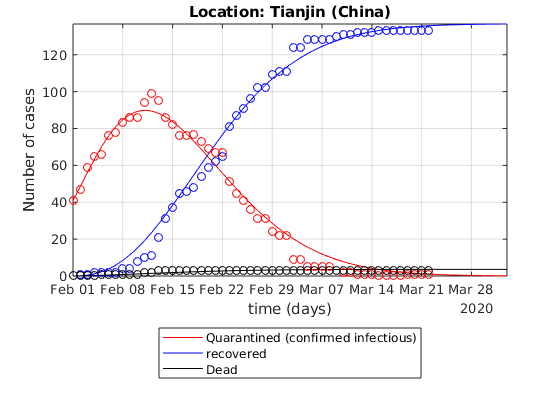

Elapsed time is 2.670706 seconds.


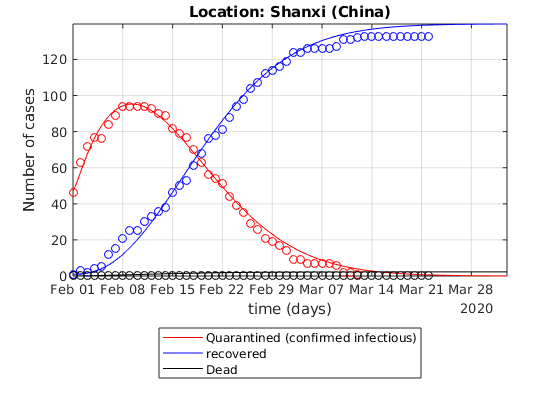

Elapsed time is 1.263116 seconds.


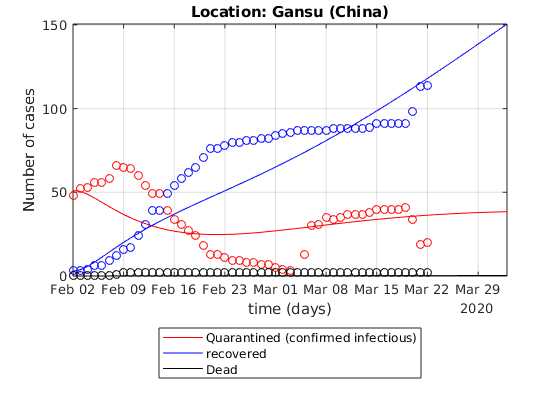

Elapsed time is 1.507351 seconds.


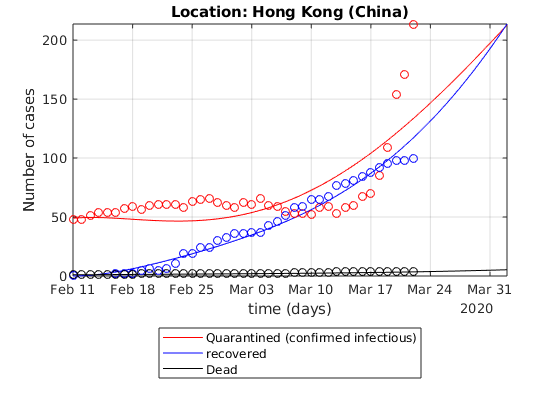

Elapsed time is 3.244106 seconds.


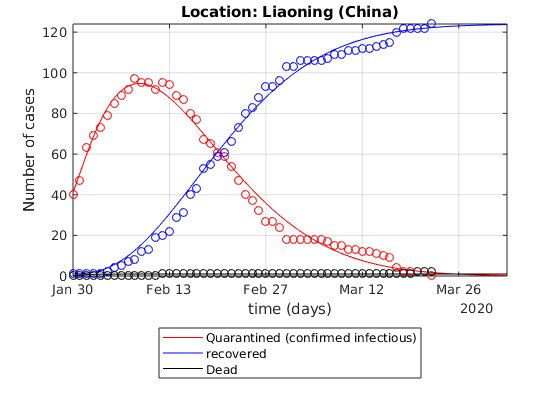

Elapsed time is 1.806714 seconds.


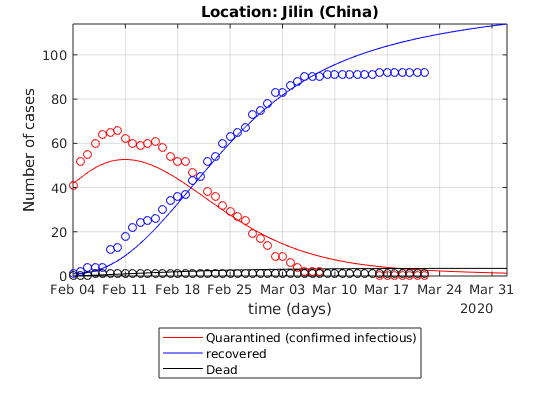

Elapsed time is 1.905327 seconds.


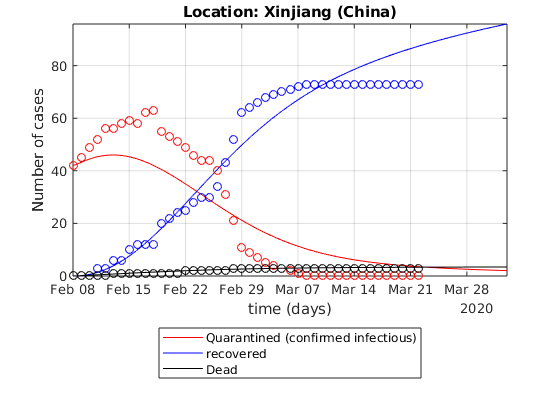

Elapsed time is 2.165214 seconds.


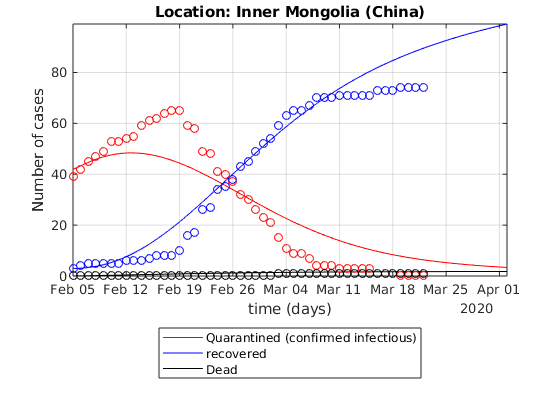

Elapsed time is 1.606527 seconds.


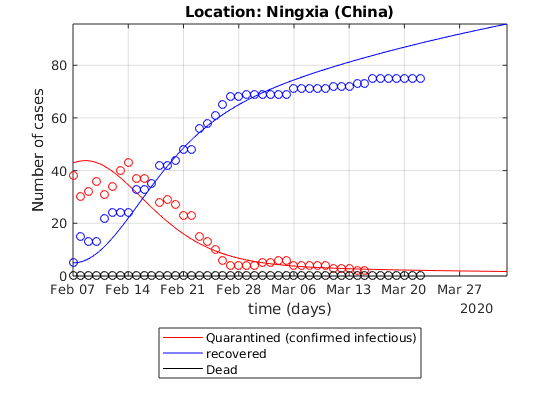

timeRef = time; % Used in the loop only

for ii = 1:numel(indLocation)
    indL = indLocation(ii); % Get location for
    Recovered = table2array(tableRecovered(indL,5:end));
    Deaths = table2array(tableDeaths(indL,5:end));
    Confirmed = table2array(tableConfirmed(indL,5:end));
    
    % Warning: a dummy value of Npop is used here. 
     Npop= 30e6; % population (It affects the values of the parameters)
     
     
    % Remove case where only few infectious are recorded (to avoid bad
    % initial conditions)
    Recovered(Confirmed<=minNum)=[];
    Deaths(Confirmed<=minNum)=[];
    time = timeRef; % trick to avoid reloading the variable "time" at each new loop
    time(Confirmed<=minNum)= [];
    Confirmed(Confirmed<=minNum)=[];
    
    % The fitting is only applied if enough data is collected (that is why
    % I use the case of China)
    if numel(Confirmed)>30 % If more than 30 days of data, run the fit
        tic
        
        % Definition of the first estimates for the parameters
        alpha_guess = 0.06; % protection rate
        beta_guess = 1.0; % Infection rate
        LT_guess = 5; % latent time in days
        QT_guess = 21; % quarantine time in days
        lambda_guess = [0.1,0.05]; % recovery rate
        kappa_guess = [0.1,0.05]; % death rate
        
        guess = [alpha_guess,beta_guess,1/LT_guess, 1/QT_guess,lambda_guess,kappa_guess];
        
        % Initial conditions
        E0 = Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
        I0 = Confirmed(1); % Initial number of infectious cases. Unknown but unlikely to be zero.
        Q0 = Confirmed(1);
        R0 = Recovered(1);
        D0 = Deaths(1);
        
        [alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
            fit_SEIQRDP(Confirmed-Recovered-Deaths,Recovered,Deaths,Npop,E0,I0,time,guess,'Display','off');
        
        % Call of the function SEIQRDP.m with the fitted parameters
        dt = 0.1; % time step
        time1 = datetime(time(1)):dt:datetime(datestr(floor(datenum(now))+datenum(10)));
        N = numel(time1);
        t = [0:N-1].*dt;
        [S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);
        
        clf;close all;
        figure
        
        subLoc = char(table2array(tableRecovered(indL,1)));
        Loc = char(table2array(tableRecovered(indL,2)));
        
        semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
        hold on
        semilogy(time,Confirmed-Recovered-Deaths,'ro',time,Recovered,'bo',time,Deaths,'ko');
        % ylim([0,1.1*Npop])
        ylabel('Number of cases')
        xlabel('time (days)')
        % leg = {'susceptible','exposed','infectious','quarantined','recovered','Dead','insusceptible'};
        leg = {'Quarantined (confirmed infectious)','recovered','Dead'};
        legend(leg{:},'location','southoutside');
        set(gcf,'color','w')
        
        %%% title %%%
        subLoc = char(table2array(tableRecovered(indL,1)));
        Loc = char(table2array(tableRecovered(indL,2)));
        title(['Location: ',subLoc,' (',Loc,')'])
        %%%%%%%%%%%%%
        
        grid on
        axis tight
        set(gca,'yscale','lin')
        toc
        
        pause(1)
    end
end